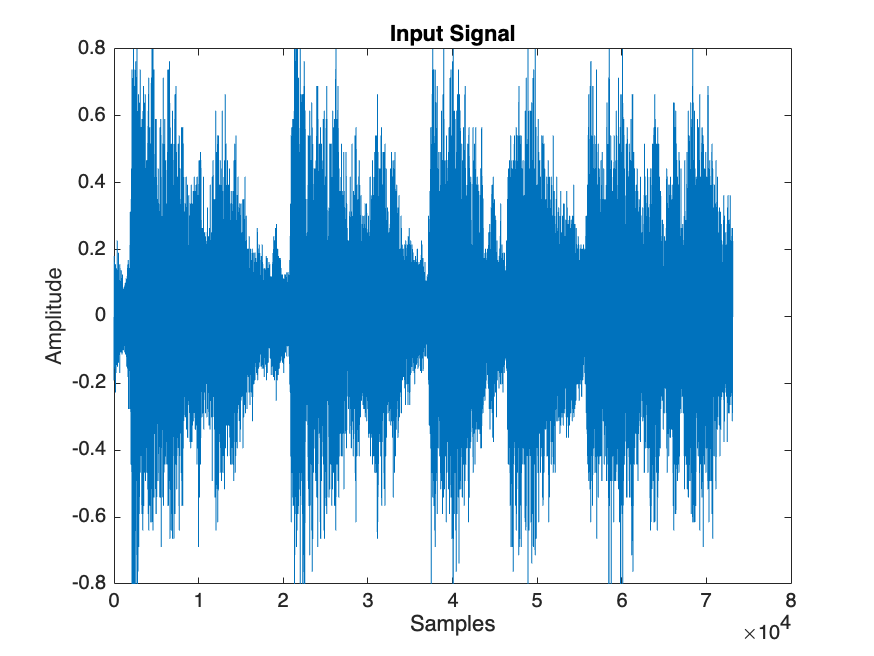

clc; clear all; close all

load handel.mat

fs=Fs;
y = y(:, 1);
original_sound = y;

figure,plot(y);
title('Input Signal');
xlabel('Samples');
ylabel('Amplitude');


disp('Playing Input Sound')

Playing Input Sound


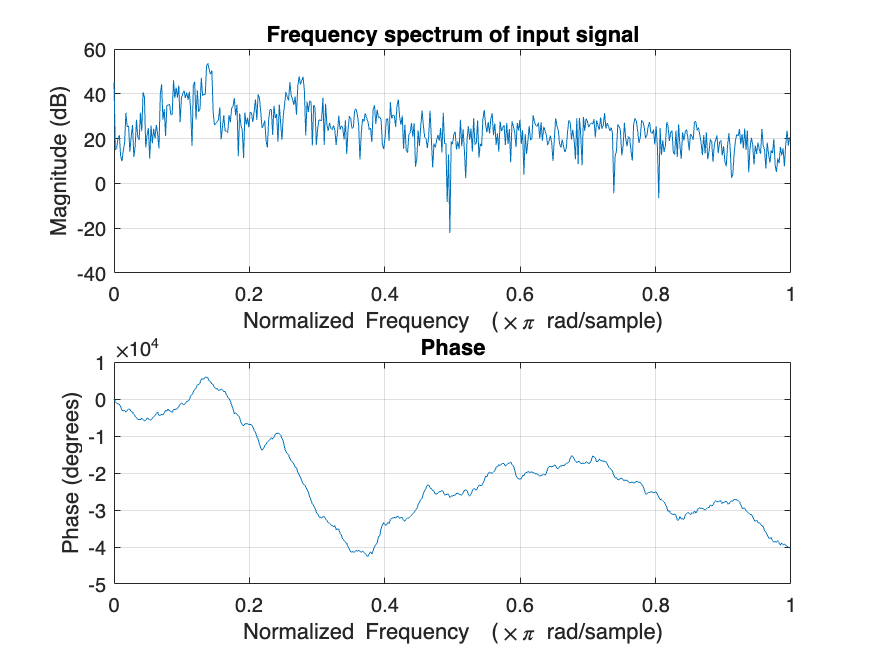

sound(y,fs);
pause(10);

figure;
freqz(y)
title('Frequency spectrum of input signal')

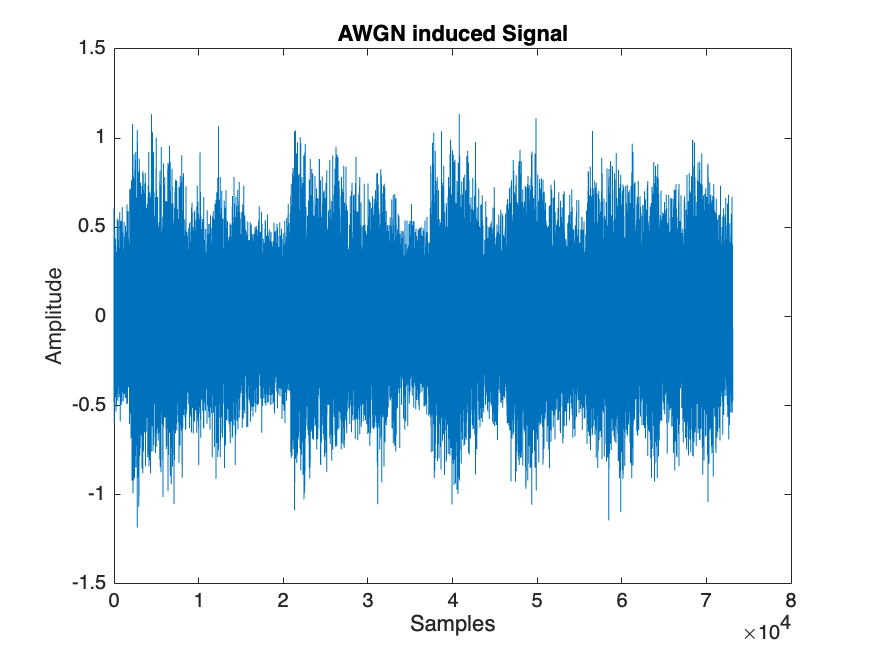

%Adding Noise to the input signal
yy = awgn(y,15); % SNR = 15 dB
noi = yy;

figure,plot(yy);
xlabel('Samples');
ylabel('Amplitude');
title('AWGN induced Signal');


disp('Playing Noisy Signal');

Playing Noisy Signal


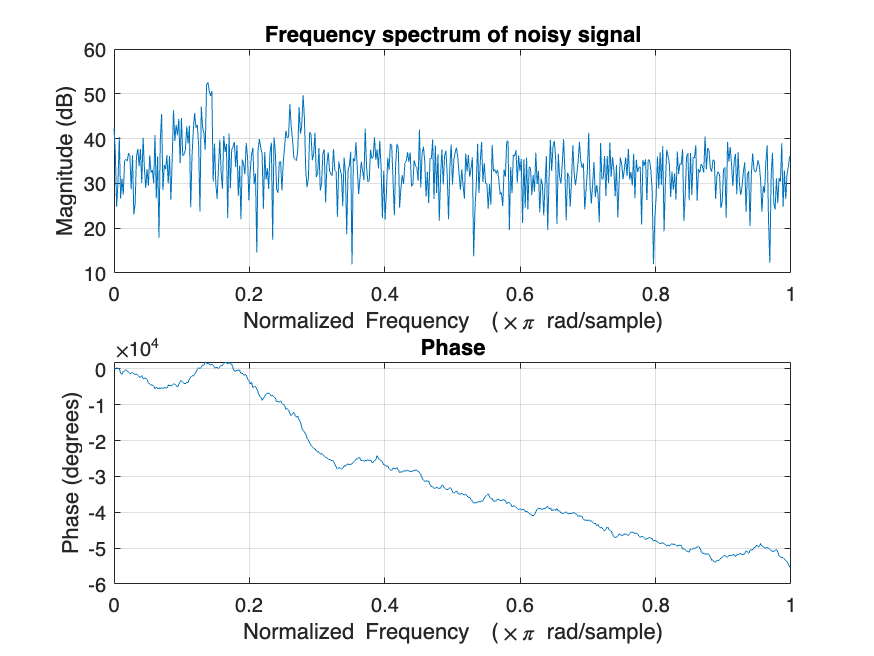

sound(yy);
pause(10);

figure;
freqz(yy)
title('Frequency spectrum of noisy signal')


mse1 = mean((original_sound(:)-yy(:)).^2)

mse1 = 0.0314

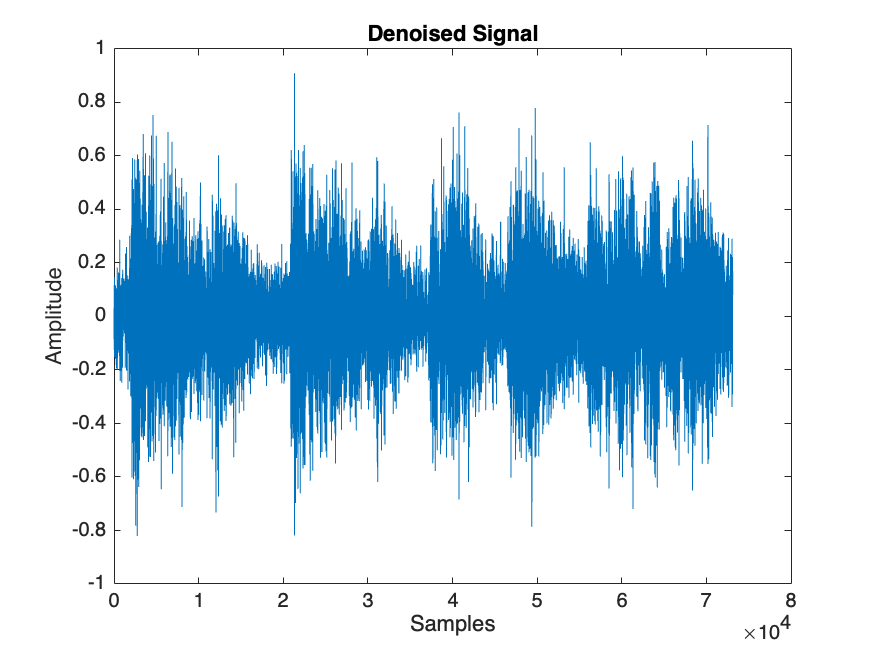

% Wavelet Based Method for Denoising of the signal
x = wdenoise(yy,'DenoisingMethod','bayes','ThresholdRule','Soft','NoiseEstimate','LevelIndependent',8,'wavelet','sym8');

figure,plot(x);
xlabel('Samples');
ylabel('Amplitude');
title('Denoised Signal');


disp('Playing denoised sound');

Playing denoised sound


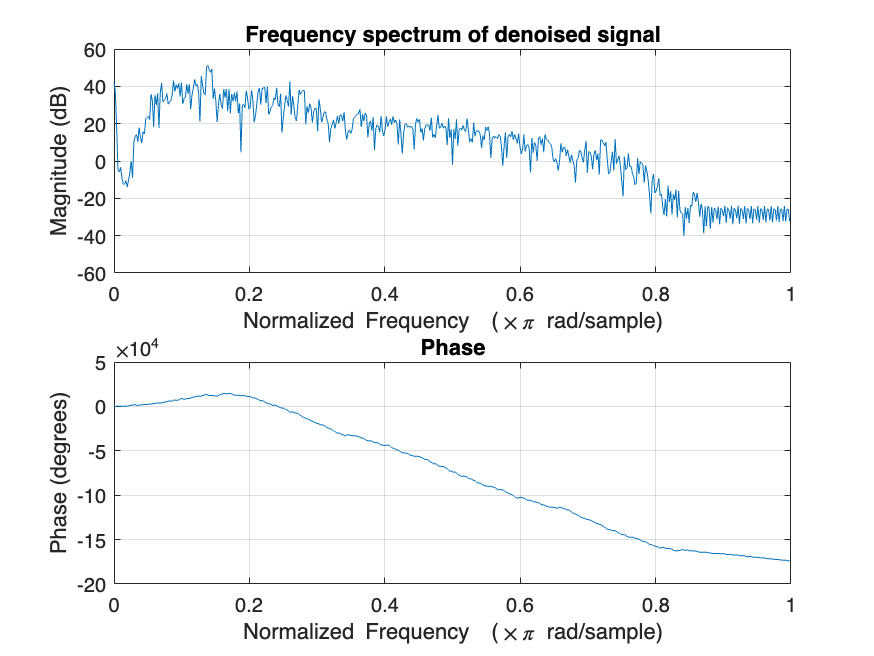

sound(x,fs);
pause(10);

figure;
freqz(x)
title('Frequency spectrum of denoised signal')


mse2 = mean((original_sound(:)-x(:)).^2)

mse2 = 0.0154

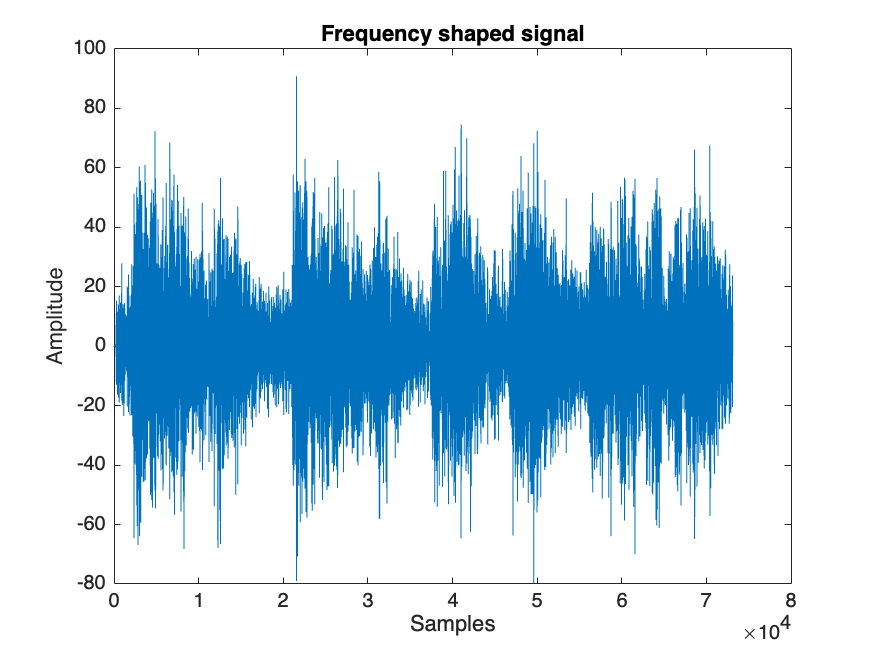

% Frequency shaper using band pass filter

T = 1/fs;
len = length(x);
p = log2(len);
p = ceil(p);
N = 2^p;
f1 = fdesign.bandpass('Fst1,Fp1,Fp2,Fst2,Ast1,Ap,Ast2',400,500,2400,2500,80,0.5,80,2*fs);
hd = design(f1,'equiripple');
y = filter(hd,x);
freqz(hd);
Gain_db = 40;
y = y*100;

figure;
plot(y);
xlabel('Samples');
ylabel('Amplitude');
title('Frequency shaped signal')


disp('Playing frequency shaped sound');

Playing frequency shaped sound


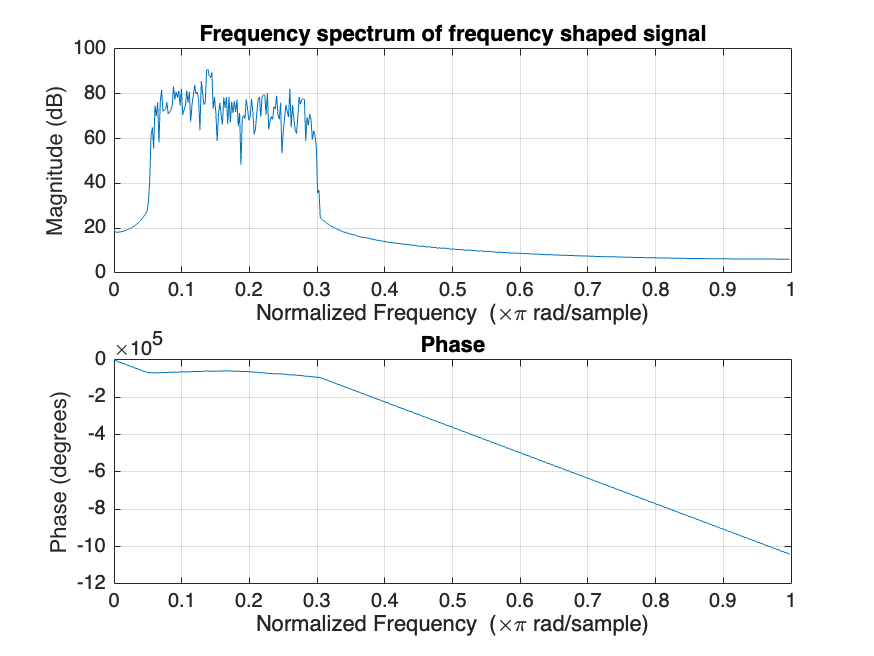

%sound(y,fs);
pause(10);

figure;
freqz(y)
title('Frequency spectrum of frequency shaped signal')

mse3 = mean((original_sound(:)-y(:)).^2)

mse3 = 215.2850

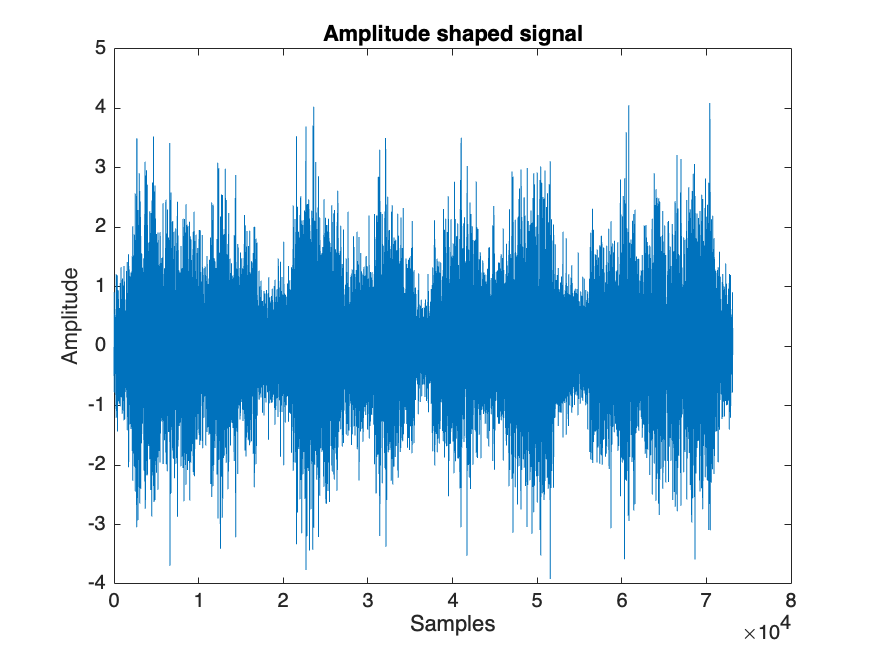


% Amplitude Shaper/Compression

out1 = fft(y);
phase = angle(out1);
mag = abs(out1)/N;
[magsig,~] = size(mag);
P_sat_db = 80;
threshold = 1000;
out = zeros(magsig,1);

for i = 1:magsig/2
    if (mag(i) > threshold)
	    mag(i) = threshold;
        mag(magsig - i) = threshold;
    end
    out(i) = mag(i)*exp(j*phase(i));
    out(magsig-i) = out(i);
end
outfinal = real(ifft(out))*10000;

figure;
plot(outfinal);
xlabel('Samples');
ylabel('Amplitude');
title('Amplitude shaped signal')


disp('Playing amplitude shaped...');

Playing amplitude shaped...


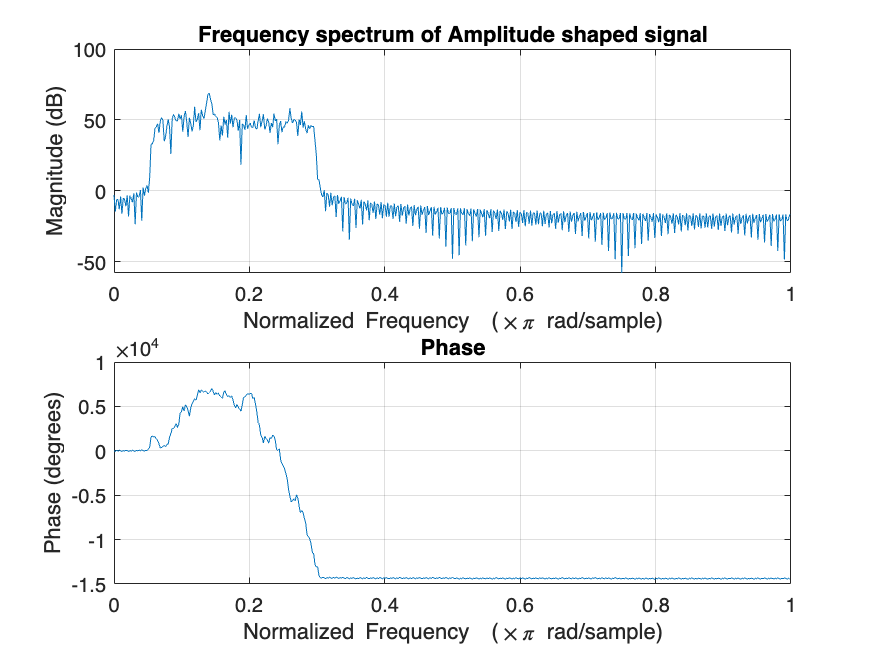

sound(outfinal,fs);
pause(10);

figure;
freqz(outfinal)
title('Frequency spectrum of Amplitude shaped signal')

mse4 = mean((original_sound(:)-outfinal(:)).^2)

mse4 = 0.6793

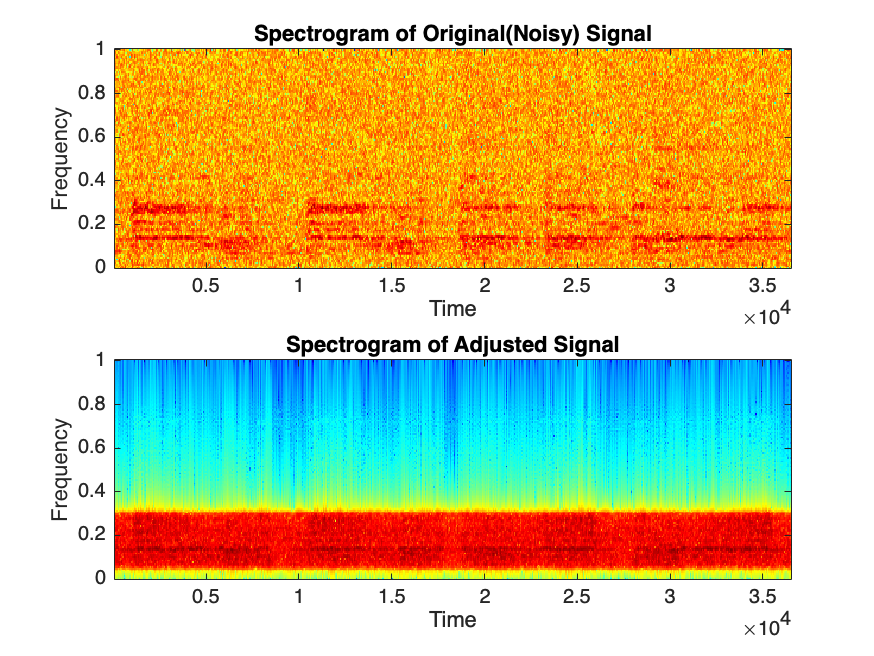

% Spectrograms 
load handel.mat
figure;
subplot(2,1,1);
specgram(noi);
title('Spectrogram of Original(Noisy) Signal');

subplot(2,1,2);
specgram(outfinal);
title('Spectrogram of Adjusted Signal');